## fig3-ABC

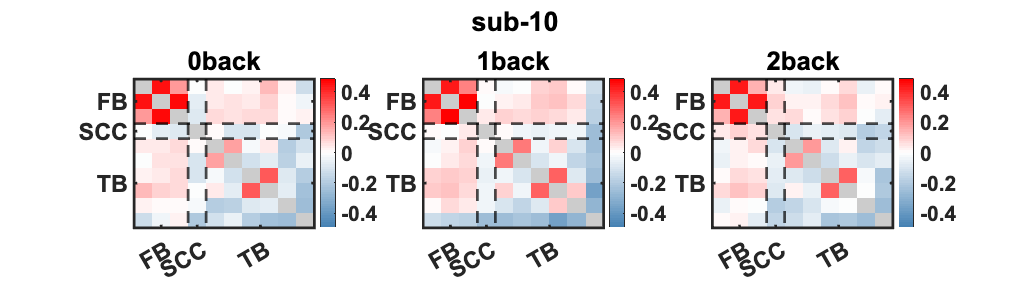

clc;clear;close all;
subjID = 'sub-10';
TFRFolder = 's01_WihtinFre';
taskG = {'resting','0back','1back','2back'};
Freq = {'theta','alpha','beta','gamma','high-gamma';[1,17],[17,37],[37,54],[54,94],[94,144]};
netG = {'FrontalB','CornorR','SpleniumCorpusC','TemporalB'};
netG_sub = {'InfFrontalB','MidFrontalB','AntCoronaR','SupCoronaR','SupParietalB','SpleniumCorpusC','TemporalB'};

load(fullfile(TFRFolder,subjID,[subjID,'_WM_FC_Alltrials.mat']));

FCres_avg = cellfun(@(x) mean(x,3,'omitnan'),FCres_whole,'UniformOutput',false);
T_avg{1,1} = FCres_avg{1,2};
T_avg{1,2} = FCres_avg{1,3};
T_avg{1,3} = FCres_avg{1,4};

%Adjust channel order
IDX = [];
for i = 1:numel(netG_sub)
    idx = find(strcmp(wmGoodChans_used(:,2),netG_sub{i}));
    IDX = [IDX;idx]; clear idx
end
T_avg = cellfun(@(x) x(IDX,IDX),T_avg,'UniformOutput',false);
temp1 = T_avg{1,1}; temp2 = T_avg{1,2}; temp3 = T_avg{1,3}; temp = [temp1(:);temp2(:);temp3(:)]; lims = max(abs(temp)); clear temp temp1 temp2 temp3;
wmGoodChans_used = wmGoodChans_used(IDX,:);

%region division
for i = 1:size(wmGoodChans_used,1)
    temp = wmGoodChans_used{i,2};
    if strcmp(temp,'InfFrontalB')|strcmp(temp,'MidFrontalB')
        wmGoodChans_used{i,6} = 'FB';
        else if strcmp(temp,'AntCoronaR')|strcmp(temp,'SupCoronaR')
                wmGoodChans_used{i,6} = 'CR';
            else if strcmp(temp,'SupParietalB')|strcmp(temp,'SpleniumCorpusC')
                    wmGoodChans_used{i,6} = 'SCC';
                else if strcmp(temp,'TemporalB')
                        wmGoodChans_used{i,6} = 'TB';
                end
            end
        end
    end
end
tab = tabulate(wmGoodChans_used(:,6));
line_loc = cell2mat(tab(:,2));  line_loc = cumsum(line_loc); line_loc(end) = []; 
if isempty(line_loc)
    line_loc = 0;
end
tick_loc = cell2mat(tab(:,2));  edges = cumsum(tick_loc); start_points = [0; edges(1:end-1)]; tick_loc = (start_points + edges) / 2; clear edges start_points;

%custom colors
custom_colors = [
    70/255, 130/255, 180/255;  
    1, 1, 1;                   
    1, 0, 0                   
];
n_colors = 64;
x_original = linspace(-1, 1, size(custom_colors, 1)); 
x_new = linspace(-1, 1, n_colors);                   
custom_colormap = interp1(x_original, custom_colors, x_new, 'linear');
nan_color = [0.8, 0.8, 0.8]; %NaN color

%figure
figure('position',[100,200,2100,580]);
titlabel = {'0back','1back','2back'};
for i = 1:3
    temp = T_avg{1,i}; temp(eye(size(temp)) == 1) = NaN;
    subplot(1,3,i); h = imagesc(temp); colormap(custom_colormap); caxis([-lims,lims]);
    set(h, 'AlphaData', ~isnan(temp)); 
    set(gca, 'Color', nan_color);  
    colorbar;
    title(titlabel{i},'FontWeight','bold', 'FontSize', 30); 
    xline(line_loc+0.5, 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
    yline(line_loc+0.5, 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
    xticks(tick_loc+0.5);xticklabels(tab(:,1));
    yticks(tick_loc+0.5);yticklabels(tab(:,1));
    set(gca, 'FontName', 'Arial','FontWeight','bold', 'FontSize', 26, 'LineWidth', 3);
end
sgtitle(subjID,'FontName', 'Arial','FontWeight','bold', 'FontSize', 30)

## fig3-DEF (Data generation only; images created with GraphPad using this data)

clc;clear;close all;
TFRFolder = 's01_WithinFre';
taskG = {'resting','0back','1back','2back'};
subjG = {'sub-01', 'sub-02', 'sub-03', 'sub-05', 'sub-06', ...
    'sub-07', 'sub-09', 'sub-10', 'sub-11', 'sub-12', ...
    'sub-13', 'sub-14', 'sub-15', 'sub-16', 'sub-17', ...
    'sub-19', 'sub-20', 'sub-21','sub-23','sub-24'};
Freq = {'theta','alpha','beta','gamma','high-gamma';[1,17],[17,37],[37,54],[54,94],[94,144]};
netG = {'FrontalB','CornorR','SpleniumCorpusC','TemporalB'};

T0 = cell(144,1);
T1 = cell(144,1);
T2 = cell(144,1);
for nSub = 1:numel(subjG)
    subjID = subjG{nSub};
    load(fullfile(TFRFolder,subjID,[subjID,'_WM_FC_Alltrials.mat']));

    FCres_avg = cellfun(@(x) mean(x,3,'omitnan'),FCres_whole,'UniformOutput',false);
    for nFB = 1:size(FCres_avg,1)
        temp0 = FCres_avg{nFB,2}; temp0 = squareform(temp0)';
        temp1 = FCres_avg{nFB,3}; temp1 = squareform(temp1)';
        temp2 = FCres_avg{nFB,4}; temp2 = squareform(temp2)';
        T0{nFB,1} = [T0{nFB,1};temp0];
        T1{nFB,1} = [T1{nFB,1};temp1];
        T2{nFB,1} = [T2{nFB,1};temp2]; clear temp0 temp1 temp2;
    end
    clear FCres_avg FCres_whole;
end

PA = []; PB = []; PC = [];
for i = 1:1
    A = T0{i,1}; PA = [PA;A];
    B = T1{i,1}; PB = [PB;B];
    C = T2{i,1}; PC = [PC;C];
end
format short
[r1 p1] = corr(PA,PB,'type','Spearman')

r1 = 0.8957

p1 = 0

[r2 p2] = corr(PA,PC,'type','Spearman')

r2 = 0.8972

p2 = 0

[r3 p3] = corr(PB,PC,'type','Spearman')

r3 = 0.9083

p3 = 0

format long e
[h1 p1] = ttest(PA,PB,'Alpha',0.01,"Tail","both")

h1 =      0

p1 =      9.999998174564813e-01

[h2 p2] = ttest(PA,PC,'Alpha',0.01,"Tail","both")

h2 =      0

p2 =      9.999998993519511e-01

[h3 p3] = ttest(PB,PC,'Alpha',0.01,"Tail","both")

h3 =      0

p3 =      9.999999175440761e-01

## fig3-G (Data generation only; images created with Rstudio using this data)

clc;clear;close all;
TFRFolder = 's01_WihtinFre';
SaveFolder = 's02_FCloadSimilarity';
mkdir(SaveFolder)
taskG = {'resting','0back','1back','2back'};
subjG = {'sub-01', 'sub-02', 'sub-03', 'sub-05', 'sub-06', ...
    'sub-07', 'sub-09', 'sub-10', 'sub-11', 'sub-12', ...
    'sub-13', 'sub-14', 'sub-15', 'sub-16', 'sub-17', ...
    'sub-19', 'sub-20', 'sub-21','sub-23','sub-24'};
Freq = {'theta','alpha','beta','gamma','high-gamma';[1,17],[17,37],[37,54],[54,94],[94,144]};
netG = {'FrontalB','CornorR','SpleniumCorpusC','TemporalB'};


T0 = cell(144,1);
T1 = cell(144,1);
T2 = cell(144,1);
for nSub = 1:numel(subjG)
    subjID = subjG{nSub};
    load(fullfile(TFRFolder,subjID,[subjID,'_WM_FC_Alltrials.mat']));

    FCres_avg = cellfun(@(x) mean(x,3,'omitnan'),FCres_whole,'UniformOutput',false);
    for nFB = 1:size(FCres_avg,1)
        temp0 = FCres_avg{nFB,2}; temp0 = squareform(temp0)';
        temp1 = FCres_avg{nFB,3}; temp1 = squareform(temp1)';
        temp2 = FCres_avg{nFB,4}; temp2 = squareform(temp2)';
        T0{nFB,1} = [T0{nFB,1};temp0];
        T1{nFB,1} = [T1{nFB,1};temp1];
        T2{nFB,1} = [T2{nFB,1};temp2]; clear temp0 temp1 temp2;
    end
    clear FCres_avg FCres_whole;
end

for nFB = 1:size(T0,1)
    A = T0{nFB,1}; B = T1{nFB,1}; C = T2{nFB,1};
    R1(nFB,1) = corr(A,B,'type','Spearman');
    R2(nFB,1) = corr(A,C,'type','Spearman');
    R3(nFB,1) = corr(B,C,'type','Spearman');
end

loadingEffect_data = cell(1,size(Freq,2));
for nFB = 1:size(Freq,2)
    idx1 = Freq{2,nFB}(1); idx2 = Freq{2,nFB}(2);
    loadingEffectA = [R1(idx1:idx2),R2(idx1:idx2),R3(idx1:idx2)];
    loadingEffect_data{1,nFB} = loadingEffectA; clear loadingEffectA;
end
save(fullfile(SaveFolder,['sub-All_','WM_FC_loadingEffect.mat']),"loadingEffect_data");


